## Assignment 1: Comparing ERP Signal Denoising Techniques

## 1. Data Loading:

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\USER\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.1 to the path
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.0' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "ERPLAB" v10.0 (see >> help eegplugin_erplab)
EEGLAB: adding "Fileio" v20230819 to the path - new version 20230822 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipf

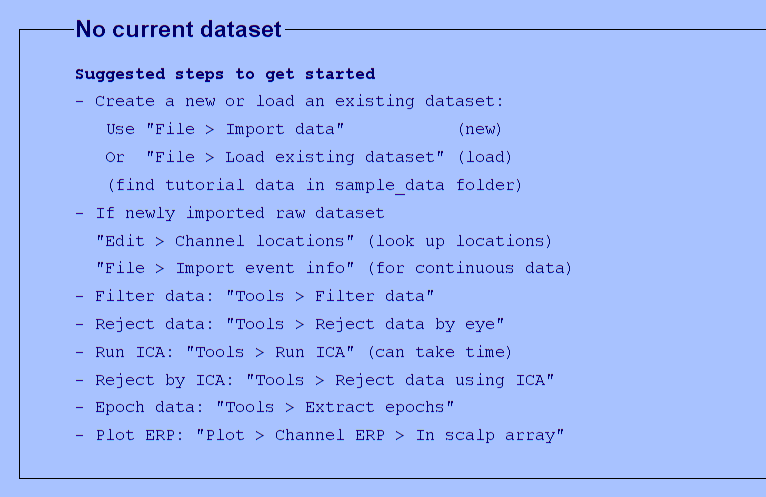

% Select the tutorial file "eeglab_data.set" located in the "sample_data” folder of EEGLAB.
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

EEG = pop_loadset('filename','eeglab_data.set','filepath','C:\\Users\\USER\\Documents\\MATLAB\\eeglab\\sample_data\\');

pop_loadset(): loading file C:\Users\USER\Documents\MATLAB\eeglab\sample_data\eeglab_data.set ...
Reading float file 'C:\Users\USER\Documents\MATLAB\eeglab\sample_data\eeglab_data.fdt'...


[ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );

Creating a new ALLEEG dataset 1


## 2-1. Denoising Techniques: Bandpass Filtering

% extract epoch data from 1 second before onset of square evnet to two second after onset of square evnet 
%EEG = pop_epoch( EEG, {  'square'  }, [-1  2], 'newname', 'Continuous EEG Data epochs', 'epochinfo', 'yes');
%EEG = pop_rmbase( EEG, [-1000 0] ,[]);

% 1. Bandpass Filtering: Use EEGLAB's FIR bandpass filter 1 ~ 50 Hz.
%EEG = pop_eegfiltnew(EEG, 'locutoff',1,'hicutoff',50,'plotfreqz',1);


## **2-2. Denoising Techniques: ASR**

% 2. ASR (Artifact Subspace Reconstruction): Use EEGLAB's ASR.
% EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,'ChannelCriterion',0.8,'LineNoiseCriterion',4,'Highpass','off','BurstCriterion',20,'WindowCriterion',0.25,'BurstRejection','on','Distance','Euclidian','WindowCriterionTolerances',[-Inf 7] );

% EEG = pop_epoch( EEG, {  'square'  }, [-1  2], 'newname', 'Continuous EEG Data epochs', 'epochinfo', 'yes');
% EEG = pop_rmbase( EEG, [-1000 0] ,[]);

## **2-3. Denoising Techniques: ICA**

% 3. ICA (Independent Component Analysis): Use EEGLAB's "ICA" function and "ICLabel" to remove artifact.
EEG = pop_epoch( EEG, {  'square'  }, [-1  2], 'newname', 'Continuous EEG Data epochs', 'epochinfo', 'yes');

pop_epoch():80 epochs selected
Epoching...
pop_epoch():80 epochs generated
pop_epoch(): checking epochs for data discontinuity


EEG = pop_rmbase( EEG, [-1000 0] ,[]);

pop_rmbase(): Removing baseline...


EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','on');

Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [32,30720] = 32 channels, 30720 frames/nFinding 32 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 30 frames per ICA weight ((1024)^2 = 30720 weights, Initial learning rate will be 0.001, block size 52.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -243.24 to 526.981
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step 1 - lrate 0.001000, wchange 15.92804791, angledelta  0.0 deg
step 2 - lrate 0.001000, wchange 0.39934036, angledelta  0.0 deg
step 3 - lrate 0.0

## 3. SNR Calculation:

% snr_value = snr(baseline_signal, peak_signal - baseline_signal);
% Find baseline and peak time indices based on the time vector of the epochs
baseline_time_indices = find(EEG.times >= -1000 & EEG.times < 0); % Assuming EEG.times is in milliseconds
peak_time_indices = find(EEG.times >= 0 & EEG.times <= 2000);

% Calculate the mean across all epochs for baseline and peak periods
baseline_data = mean(mean(EEG.data(:, baseline_time_indices, :), 3), 2);
peak_data = mean(mean(EEG.data(:, peak_time_indices, :), 3), 2);

% Compute SNR
snr_values = snr(baseline_data, peak_data - baseline_data);

disp(snr_values)

  -44.3863



You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


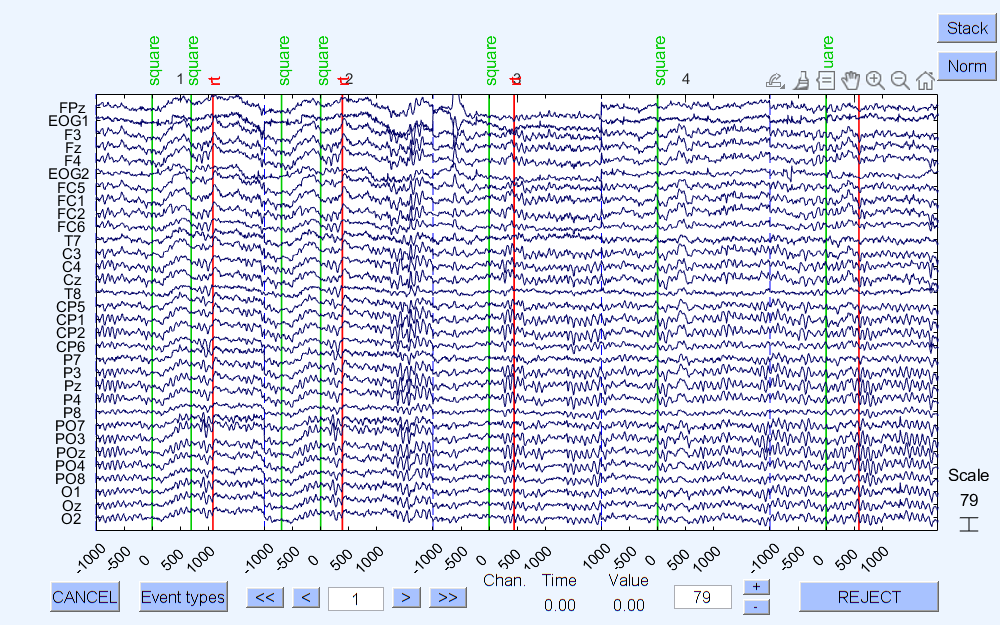

pop_eegplot( EEG, 1, 1, 1);

## 4. Report:

% Describe the denoising techniques used.
% Band-pass filtering 操作傅立葉轉換將特定頻率內容保存
% ASR 使用主成分分析，將資料切成數個小段，再修正變異數過大的區段
% ICA 將信號分離成許多獨立項目，移除噪聲

% Compare SNRs.
%       Band-pass filtering -> -3.4335
%       先filtering再extract epoch -> -44.8361
%       ASR (沒辦法先extract epoch再執行) -> -39.0805
%       ICA -> -44.3863

% Discuss pros and cons.
%       目前看起來Band-pass最好，但也有可能是我不太會處理數據導致雜訊過多:(
%       ASR的缺點是沒辦法先將連續的資料離散化

% Conclude with the best method for ERP denoising based on SNR and visual assessment.
%       同上，應該是Band-pass最有效